figure
x = [csvlist1(:, 1)];
y = [csvlist1(:, 2)];
z = [csvlist1(:, 3)];
x = table2array(x);
y = table2array(y);
z = table2array(z);

L = [sum(x.^2) sum(x.*y) sum(x.*z) sum(x);
     sum(x.*y) sum(y.^2) sum(y.*z) sum(y);
     sum(x.*z) sum(y.*z) sum(z.^2) sum(z);
     sum(x) sum(y) sum(z) length(x)]

L = 	1.0e+07 *

    2.5255    0.4755   -1.7645    0.0100
    0.4755    0.6860   -0.4835    0.0024
   -1.7645   -0.4835    2.1170   -0.0083
    0.0100    0.0024   -0.0083    0.0001


 
M = [-sum(x.^3 + x.*y.^2 + x.*z.^2);
     -sum(x.^2.*y + y.^3 + y.*z.^2);
     -sum(x.^2.*z + y.^2.*z + z.^3);
     -sum(x.^2 + y.^2 + z.^2)]

M = 	1.0e+10 *

   -1.2452
   -0.2943
    1.2224
   -0.0053


 
W = inv(L)*M

W = 	1.0e+04 *

   -0.0249
   -0.0006
    0.0415
    1.1900



R = ((W(1)^2 + W(2)^2 + W(3)^2) / 4 - W(4)) ^(1 / 2)

R = 215.9998

O = [-W(1) / 2; -W(2) / 2; -W(3) / 2]

O =   124.4515
    2.9969
 -207.5064


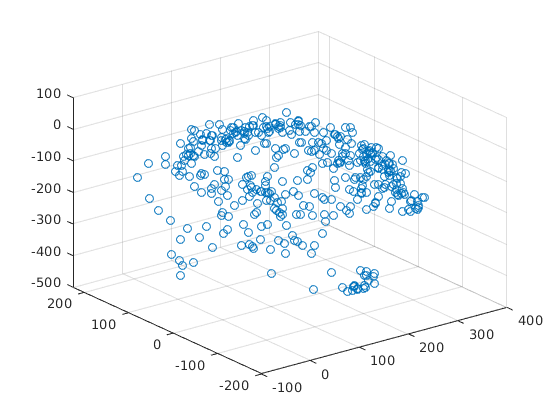


scatter3(x, y, z)